load sampleEEGdata.mat

freq = linspace(2,30,5);
time = -1:1/EEG.srate:1;

wlet_space = zeros([length(freq), length(time)]);

for fi = 1:length(freq)
    s = 6/(2*pi*freq(fi));
    g_window = exp(-time.^2./(2*s^2));
    s_wave = exp(2*pi*1i*freq(fi)*time);
    wlet_space(fi,:) = g_window .* s_wave;
end

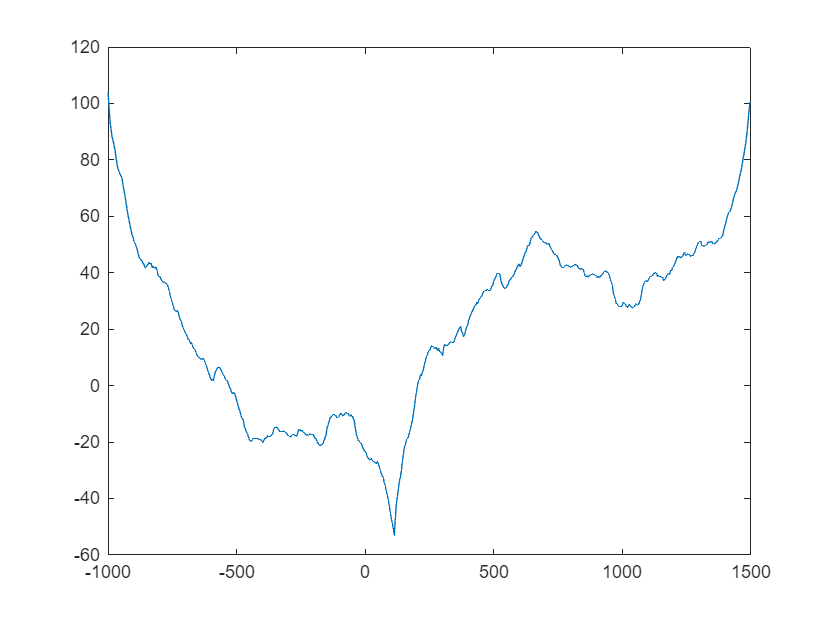

signals = EEG.data(:,:,87);
n_conv = EEG.pnts + length(time) - 1;

fft_s = fft(signals', n_conv)';
fft_w = fft(wlet_space', n_conv)';
fft_c = zeros([EEG.nbchan,n_conv,length(freq)]);

for i = 1:length(freq)
    fft_c(:,:,i) = fft_s.*fft_w(i,:);
end

conv_result = ifft(fft_c, EEG.pnts,2);
figure;
plot(EEG.times, conv_result(1,:,1))


conv_result = permute(conv_result, [2 3 1]);


result = zeros([EEG.pnts, length(freq),EEG.nbchan,2]);
result(:,:,:,1) = abs(conv_result).^2;
result(:,:,:,2) = angle(conv_result);

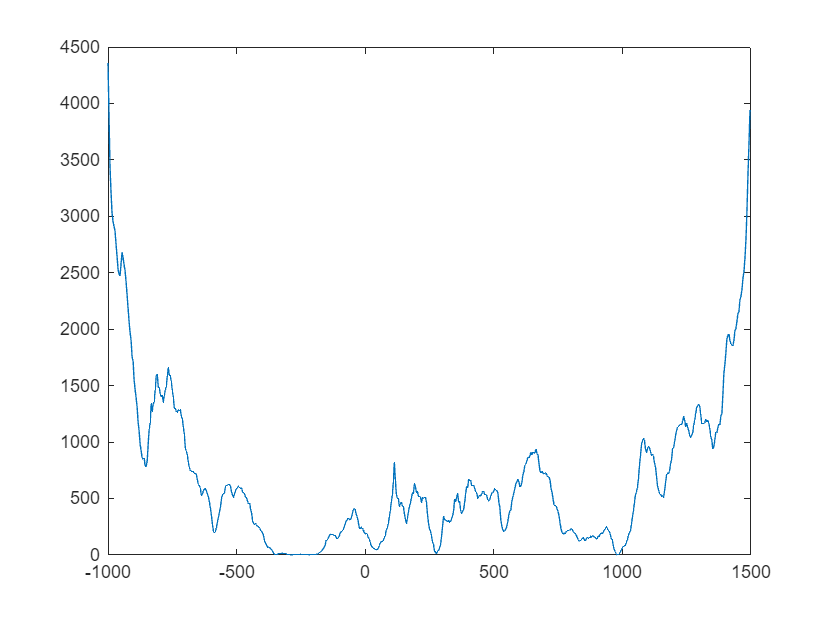

figure;
plot(EEG.times, result(:,1,4,1))

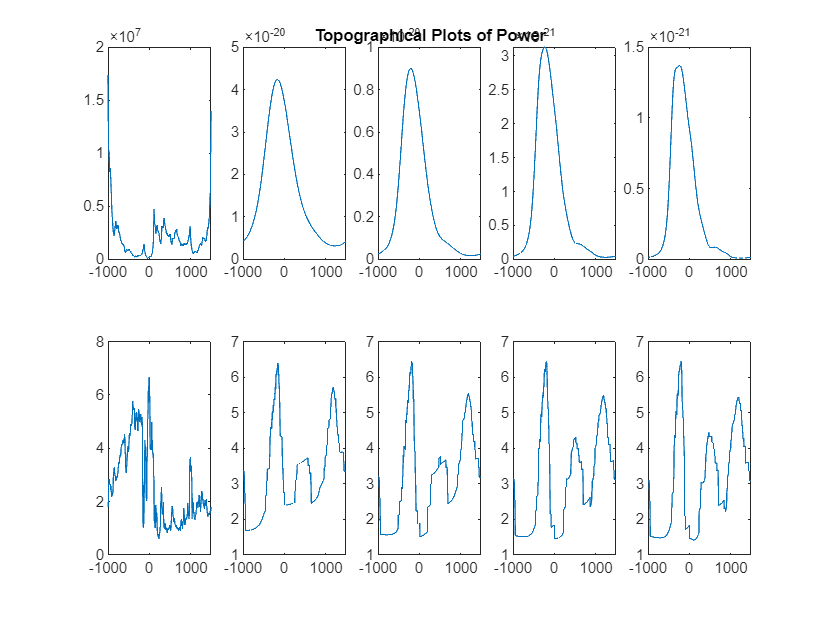


figure;
for i  = 1:5
    subplot(2,5,i)
    power = squeeze(result(:,i,:,1))';
    var_power = var(power);
    plot(EEG.times, var_power)
    subplot(2,5,i + 5)
    phase = squeeze(result(:,i,:,2))';
    var_phase = var(phase);
    plot(EEG.times, var_phase)
end

subplot(2,5,3)
title("Topographical Plots of Power")

time_index = find(EEG.times >= 180,1)

time_index = 304

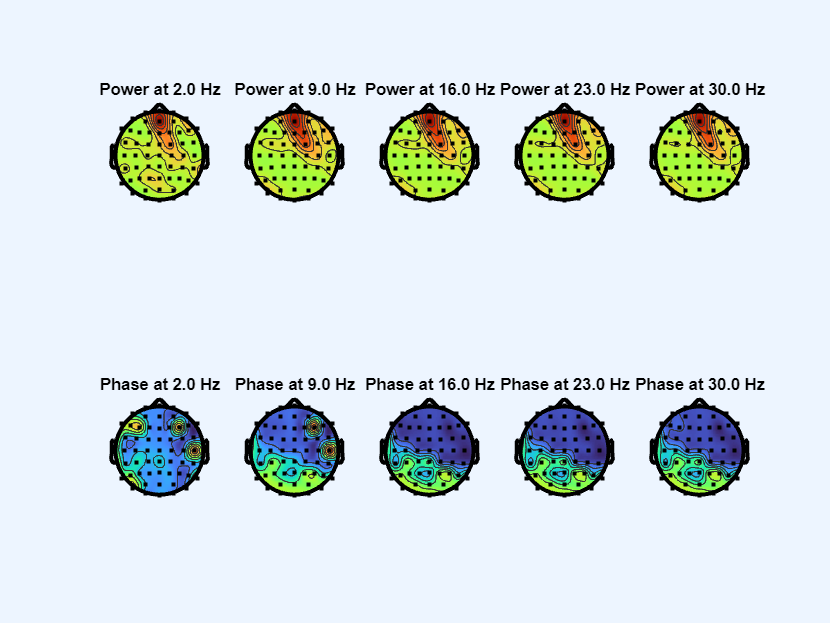


figure;

for freq_idx = 1:length(freq)

    % Power subplot
    subplot(2, 5, freq_idx);
    topoplot(squeeze(result(time_index, freq_idx, :, 1)), EEG.chanlocs, 'electrodes', 'on', 'plotrad', .53);
    title(sprintf('Power at %.1f Hz', freq(freq_idx)));
    
    % Phase subplot
    subplot(2, 5, freq_idx + 5);
    topoplot(squeeze(result(time_index, freq_idx, :, 2)), EEG.chanlocs,'electrodes', 'on', 'plotrad', .53);
    title(sprintf('Phase at %.1f Hz', freq(freq_idx)));
end


time_index = find(EEG.times >= 360, 1)

time_index = 350

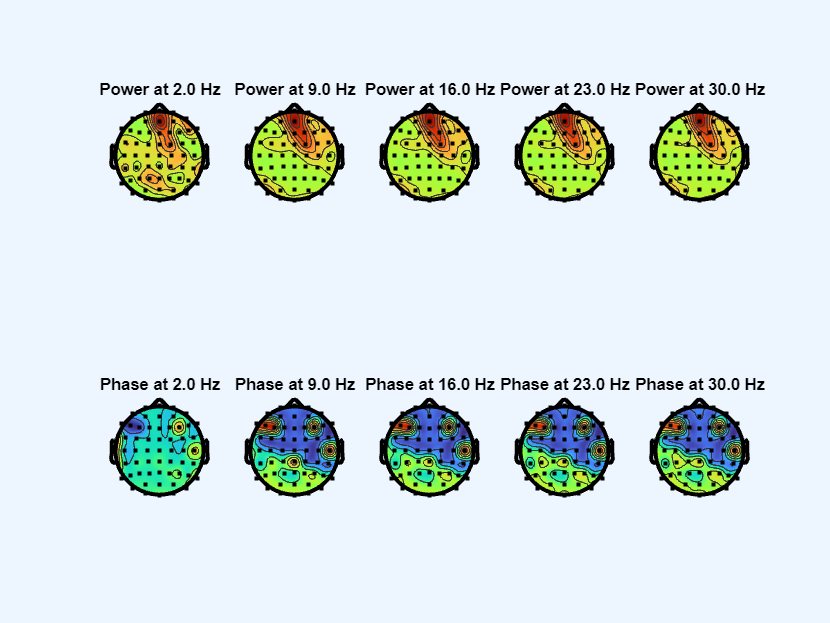


figure;

for freq_idx = 1:length(freq)

    % Power subplot
    subplot(2, 5, freq_idx);
    topoplot(squeeze(result(time_index, freq_idx, :, 1)), EEG.chanlocs, 'electrodes', 'on', 'plotrad', .53);
    title(sprintf('Power at %.1f Hz', freq(freq_idx)));
    
    % Phase subplot
    subplot(2, 5, freq_idx + 5);
    topoplot(squeeze(result(time_index, freq_idx, :, 2)), EEG.chanlocs,'electrodes', 'on', 'plotrad', .53);
    title(sprintf('Phase at %.1f Hz', freq(freq_idx)));
end